Controllo se è rimasta aperta la porta seriale

if( exist('STM32_ser') );
    delete(STM32_ser);
    clear STM32_ser;
end

Connetto alla seriale

porte_libere = serialportlist("available")

porte_libere = "COM6"

STM32_ser = serialport(porte_libere(end), 1000000, Timeout=2);

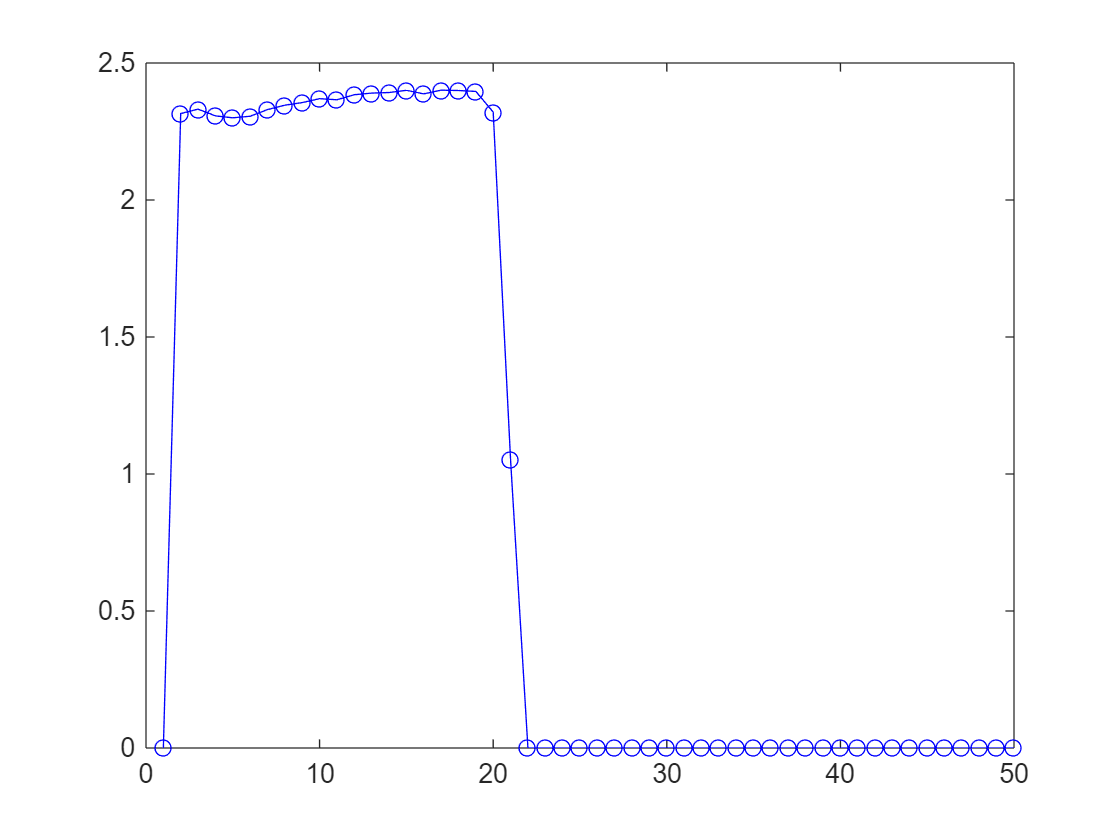

buff_size = 50;
f = figure(1);

while 1
    STM32_ser.write('?','char');
    
    data = STM32_ser.read(buff_size,'uint16') ./ 2^16 * 3.3;

    f = figure(1);
    plot(1:length(data), data, 'b-o');
    ylim([0,3.3])
    drawnow
end